%% MODELADO NUMÉRICO TRANSITORIO DEL TRANSPORTE DE CALOR 1D
% Basado estrictamente en el informe: MN_P2_Grupo_4.pdf
clear; clc; close all;

%% 0. CONFIGURACIÓN PARA EVITAR WARNINGS DE FUENTES TEX
set(groot, 'defaultTextInterpreter', 'none');
set(groot, 'defaultAxesTickLabelInterpreter', 'none');
set(groot, 'defaultLegendInterpreter', 'none');

%% 1. PARÁMETROS BASE DEL MODELO (Paginas 2 y 3 del informe)
L = 1.0;                 % Longitud de la linea de corriente (m)
N = 51;                  % Numero de nodos
dx = L / (N - 1);
x = linspace(0, L, N)';

v = 0.5;                 % Velocidad constante del fluido (m/s)
alpha0 = 0.01;           % Difusividad termica de referencia (m^2/s)
beta = 0.2;              % Coeficiente de variacion lineal
T0 = 0.0;                % Temperatura de referencia (C)

T1 = 100.0;              % Temperatura corriente libre (x=0)
TN = 0.0;                % Temperatura pared cilindro (x=L)

T_final = 2.0;           % Tiempo total de simulacion (s)
h = 0.01;                % Paso de tiempo dt
num_pasos = round(T_final / h);

% Coeficiente diagonal SDIRK4 (gamma = 1/4)
gamma = 1/4;

%% 2. CONDICIÓN INICIAL Y FIGURA
T = TN * ones(N, 1);
T(1) = T1;               % Condicion Inicial (Pagina 2)

figure('Name', 'Evolucion del Frente Termico 1D', 'Position', [200, 200, 750, 450]);
h_plot = plot(x, T, 'b-', 'LineWidth', 2);
hold on;
yline((T1+TN)/2, 'k--', 'Temperatura Media (50 C)');
title('Transporte Transitorio de Calor 1D');
xlabel('Posicion x (m)'); 
ylabel('Temperatura T (C)');
grid on; 
ylim([-5, 105]);

%% 3. BUCLE TEMPORAL (INTEGRACIÓN TRANSITORIA CON SDIRK4)
tic;
fprintf('Iniciando simulacion SDIRK4 + Newton-Raphson + Gauss-Seidel...\n');

Iniciando simulacion SDIRK4 + Newton-Raphson + Gauss-Seidel...


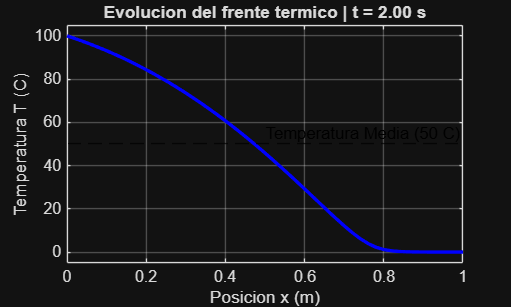


for n = 1:num_pasos
    t = n * h;
    T_old = T;
    
    % Etapa 1 de SDIRK4 (Resolver sistema no lineal)
    r1 = T_old;
    [U1, ~, ~] = newton_raphson_sdirk(T_old, r1, h, gamma, v, alpha0, beta, T0, dx, N, 1e-6);
    
    T = U1;
    T(1) = T1; T(N) = TN; % Imponer fronteras Dirichlet fijas
    
    % Graficacion animada en tiempo real
    if mod(n, 5) == 0
        set(h_plot, 'YData', T);
        title(sprintf('Evolucion del frente termico | t = %.2f s', t));
        drawnow;
    end
end

tiempo_cpu = toc;

%% 4. CUANTIFICACIÓN DEL FRENTE TÉRMICO Y RESULTADOS
T_media = (T1 + TN) / 2;

% Posicion del frente termico (donde T alcanza el valor medio de 50 C)
x_frente = interp1(T(2:N-1), x(2:N-1), T_media);

fprintf('\n=======================================================\n');

fprintf('         RESULTADOS DE LA SIMULACIÓN COMPLETA          \n');

         RESULTADOS DE LA SIMULACIÓN COMPLETA          


fprintf('=======================================================\n');

fprintf('Tiempo de procesamiento CPU: %.4f segundos\n', tiempo_cpu);

Tiempo de procesamiento CPU: 4.9939 segundos


fprintf('Posicion final del frente termico (T = %.1f C): x = %.4f m\n', T_media, x_frente);

Posicion final del frente termico (T = 50.0 C): x = 0.4731 m


fprintf('=======================================================\n');